Get attributes from h5 files for analysis using h5utils.m

import h5utils.*

% Go to directory with h5 files
cd '/home/mtb/Redwood/Data/180907_wavFiles/h5files'

h5files = dir('*.h5');
perm = 'r'; % read only

h5 = h5utils();

% Get attribute names (fields) from a file
fid = h5.open(h5files(1).name, perm);
fields = h5.get_subgroups(fid, '/'); % contains names of all the attributes

% prep for PCA on the 22 PAFs as mentioned in the 
% zebra finch acoustic feature paper and on the
% mps and spectrogram matrices
pafs = ["meantime","stdtime","skewtime", "kurtosistime",...
    "entropytime","maxAmp","rms", "q1","q2","q3","meanspect",...
    "stdspect", "kurtosisspect","skewspect","entropyspect",...
    "f0","sal","f0_2","voice2percent","maxfund","minfund","cvfund"];
pafs_locs = find(contains(fields,pafs)); % get location of each PAF 
pafs_matrix = nan(length(h5files),length(pafs_locs));

mps_loc = find(contains(fields, 'mps'));
mps_matrix = nan(length(h5files),95950);% 95950 = # of mps values

spectro_loc = find(contains(fields, 'spectro'));
spectro_matrix = nan(length(h5files),380000);% 380000 = # of spectrogram values

Out of memory. Type "help memory" for your options.

% Fill the three matrices for PCA
for ii = 1:length(h5files)
    fid = h5.open(h5files(ii).name, perm);
    
    mps = h5.get_ds(fid, fields{mps_loc});%outputs 101x950 matrix
    mps_vec = mps(:); % mps_vec(1:101) = mps(:,1)
    mps_matrix(ii,:) = mps_vec;
    
    spectro = h5.get_ds(fid, fields{spectro_loc});%outputs 400x950 matrix
    spectro_vec = spectro(:); 
    spectro_matrix(ii,:) = spectro_vec;
    
    % Fill ith row and kth column of pafs_matrix with the
    % average of the kth attribute of the ith h5 file
    for jj = 1:length(pafs_locs)
        kk = pafs_locs(jj);
        attribute = h5.get_ds(fid, fields{kk});
        pafs_matrix(ii,jj) = nanmean(attribute);
    end
end


PCA

% standardize matrices
paf_mu = nanmean(pafs_matrix);
paf_sigma = nanstd(pafs_matrix);
pafs_norm = (pafs_matrix-repmat(paf_mu,length(pafs_matrix),1))./repmat(paf_sigma,length(pafs_matrix),1);

mps_mu = nanmean(mps_matrix);
mps_sigma = nanstd(mps_matrix);
mps_norm = (mps_matrix-repmat(mps_mu,length(mps_matrix),1))./repmat(mps_sigma,length(mps_matrix),1);

spectro_mu = nanmean(spectro_matrix);
spectro_sigma = nanstd(spectro_matrix);
spectro_norm = (spectro_matrix-repmat(spectro_mu,length(spectro_matrix),1))./repmat(spectro_sigma,length(spectro_matrix),1);

% PCA
[paf_coeff,paf_score,paf_latent,paf_tsquared,paf_explained] = pca(pafs_norm);
[mps_coeff,mps_score,mps_latent,mps_tsquared,mps_explained] = pca(mps_norm);
[spectro_coeff,spectro_score,spectro_latent,spectro_tsquared,spectro_explained] = pca(spectro_norm);

PAFs

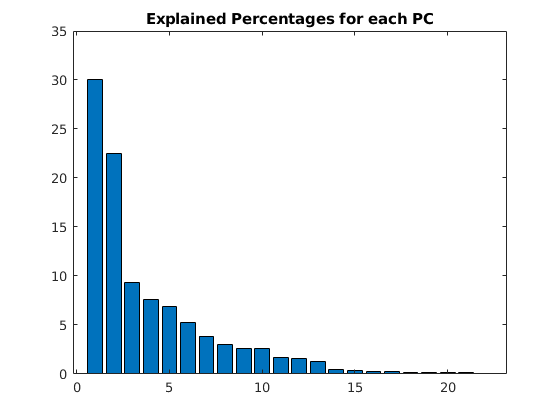

% Plot explained values
bar(1:length(paf_explained), paf_explained)
title("PAFs Explained Percentages for each PC")

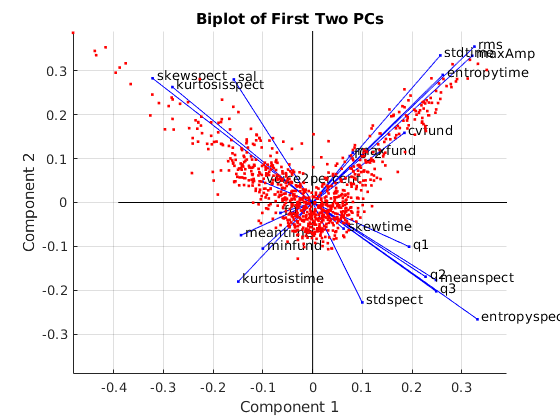

%Plot data on first two PC's
biplot(paf_coeff(:,1:2),'Scores',paf_score(:,1:2),'VarLabels',fields(pafs_locs));
title("PAFs Biplot of First Two PCs")

MPS

% Plot explained values
bar(1:length(mps_explained), mps_explained)
title("MPS Explained Percentages for each PC")

%Plot data on first two PC's
biplot(paf_coeff(:,1:2),'Scores',paf_score(:,1:2));
title("Biplot of First Two PCs")

Spectrogram

% Plot explained values
bar(1:length(spectro_explained), spectro_explained)
title("Spectrogram Explained Percentages for each PC")

%Plot data on first two PC's
biplot(spectro_coeff(:,1:2),'Scores',spectro_score(:,1:2));
title("Spectrogram Biplot of First Two PCs")

Get some stats on each field

% RMS
fn = 'rms';
fn_loc = find(contains(fields, fn));

RMS = Feature_matrix(:,fn_loc);
mean_RMS = mean(RMS);
std_RMS = std(RMS);
histogram(RMS, 10)
title('RMS')


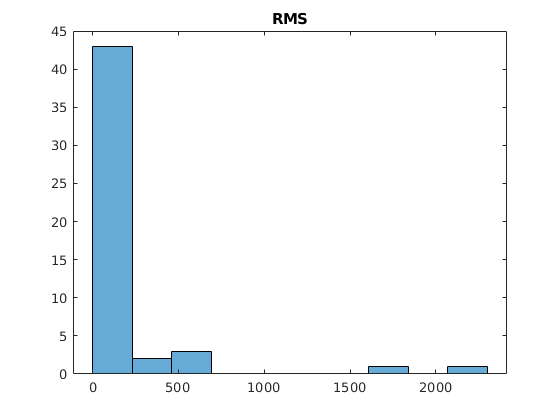

% entropy time
fn = 'entropytime';
fn_loc = find(contains(fields, fn));

enTime = Feature_matrix(:,fn_loc);

mean_et = mean(enTime);
std_et = std(enTime);
histogram(enTime)
title('Entropy Time')


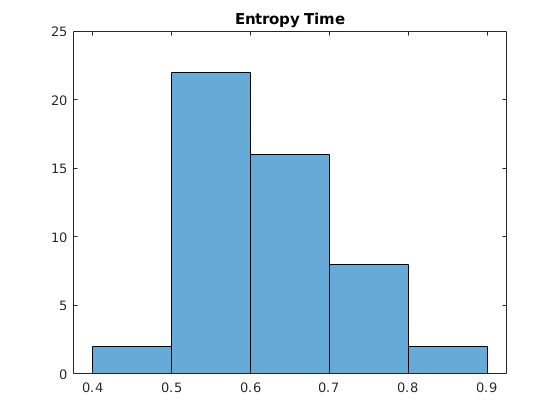

%saliency
fn = 'sal';
fn_loc = find(contains(fields, fn));

saliency = Feature_matrix(:,fn_loc);

mean_sal = mean(saliency);
histogram(saliency, 10)
title('Saliency')

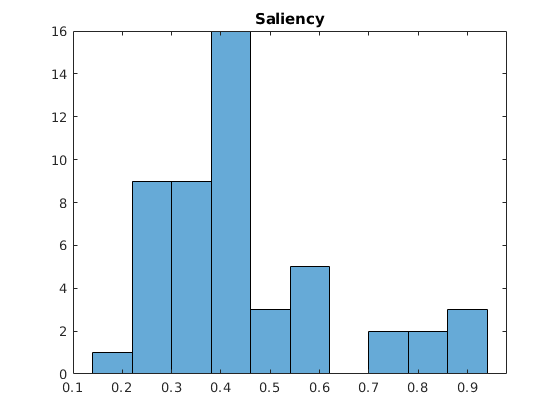

%standard deviation of time
fn = 'stdtime';
fn_loc = find(contains(fields, fn));

std_time = Feature_matrix(:,fn_loc);
histogram(std_time, 10)

title('Standard Deviation of Time')

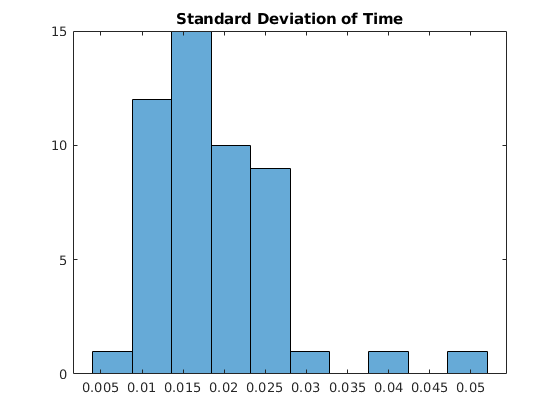

%Mean spectrum
fn = 'meanspect';
fn_loc = find(contains(fields, fn));

mean_spect = Feature_matrix(:,fn_loc);
histogram(mean_spect,10 )

title('Mean Spectrum')

Quick graphing for further analysis

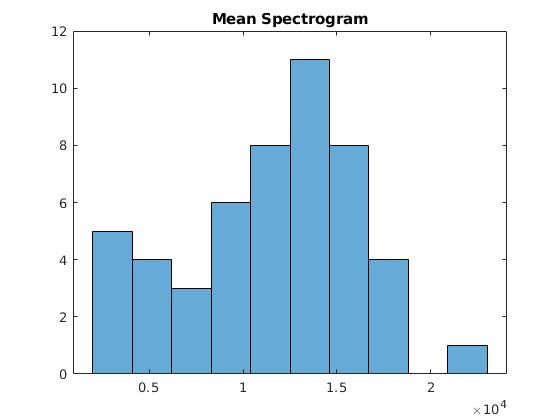

scatter(saliency,RMS)
xlabel('Saliency')
ylabel('RMS')

scatter(saliency,std_time)
xlabel('Saliency')
ylabel('STD of Time')

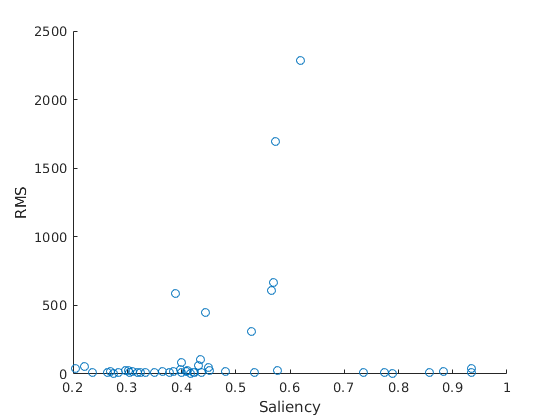

scatter(saliency,enTime)
xlabel('Saliency')

ylabel('Entropy Time')

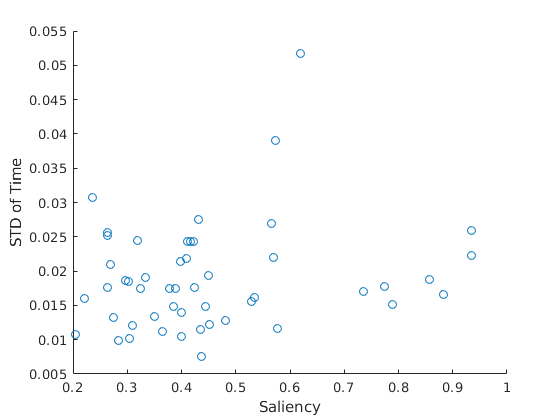

scatter(saliency,mean_spect)
xlabel('Saliency')

ylabel('Mean Spectrum')

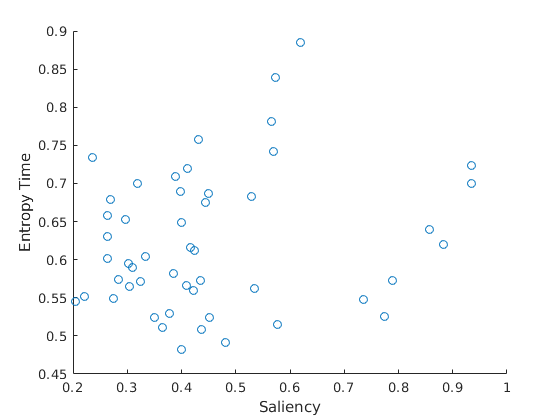

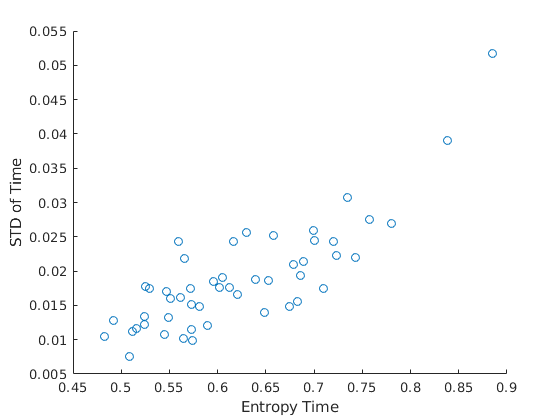

scatter(mean_spect,std_time)
xlabel('Mean Spectrum')

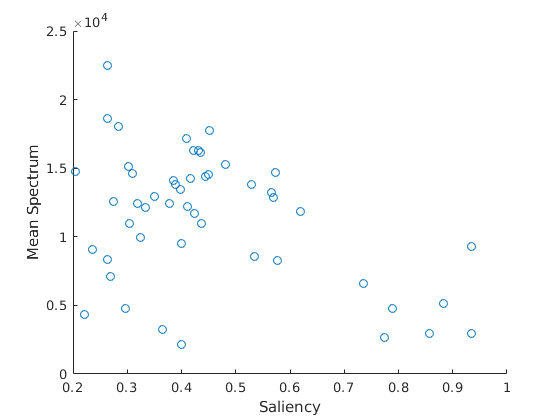

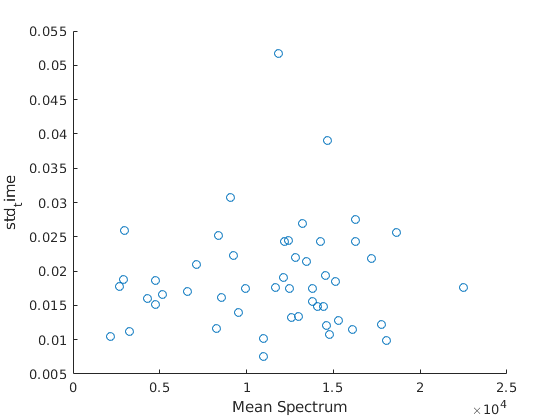

ylabel('std_time')